# ELEX7620 Lab 1

Name:  Ryan Wong, A00958475, and set:T

Objective:  to simulate and measure a 2nd order Butterworth lowpass filter

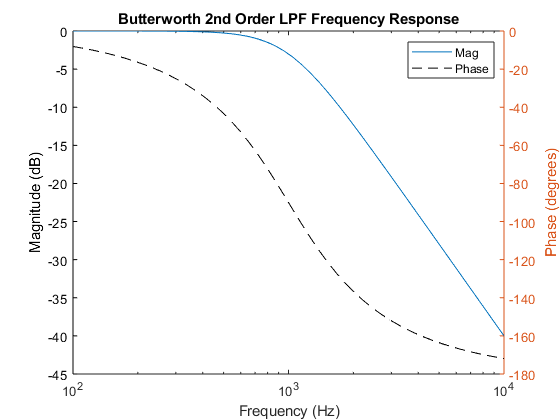

fc=1000;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
zeta = sqrt(2)^(-1);

%modify the code below to create the transfer function
%store transfer function in variable name H
b = wc^2;
a = [1 2*zeta*wc wc^2];
H = tf(b,a); 

%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Butterworth 2nd Order LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Calculate Component Values for Sallen Key Filter

## 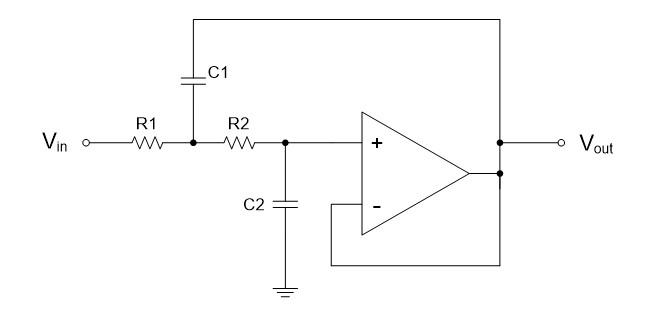

%Show your work for the steps below by inserting some documentation above or below this code block


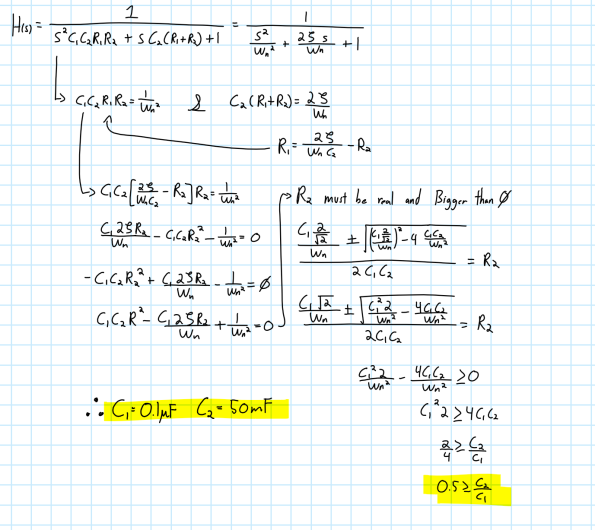

%Specify the constraint for C2 / C1
% C2 must be smaller than or equal to half of C1
C1 = 0.1e-6; %2A104J
%Choose and set C2
C2 = 33000 * 10^(-12);%2A333J
%Calculate the values for R1 and R2
A = C1*C2;
B = -1 * C1 * sqrt(2) * wc^(-1);
C = (wc)^(-2);

R2 = (-B + sqrt(B^2 - (4 * A * C)))/(2 * A)

R2 = 5.3988e+03

R1 = (-B - sqrt(B^2 - (4 * A * C)))/(2 * A)

R1 = 1.4218e+03

## LTSPICE Schematic

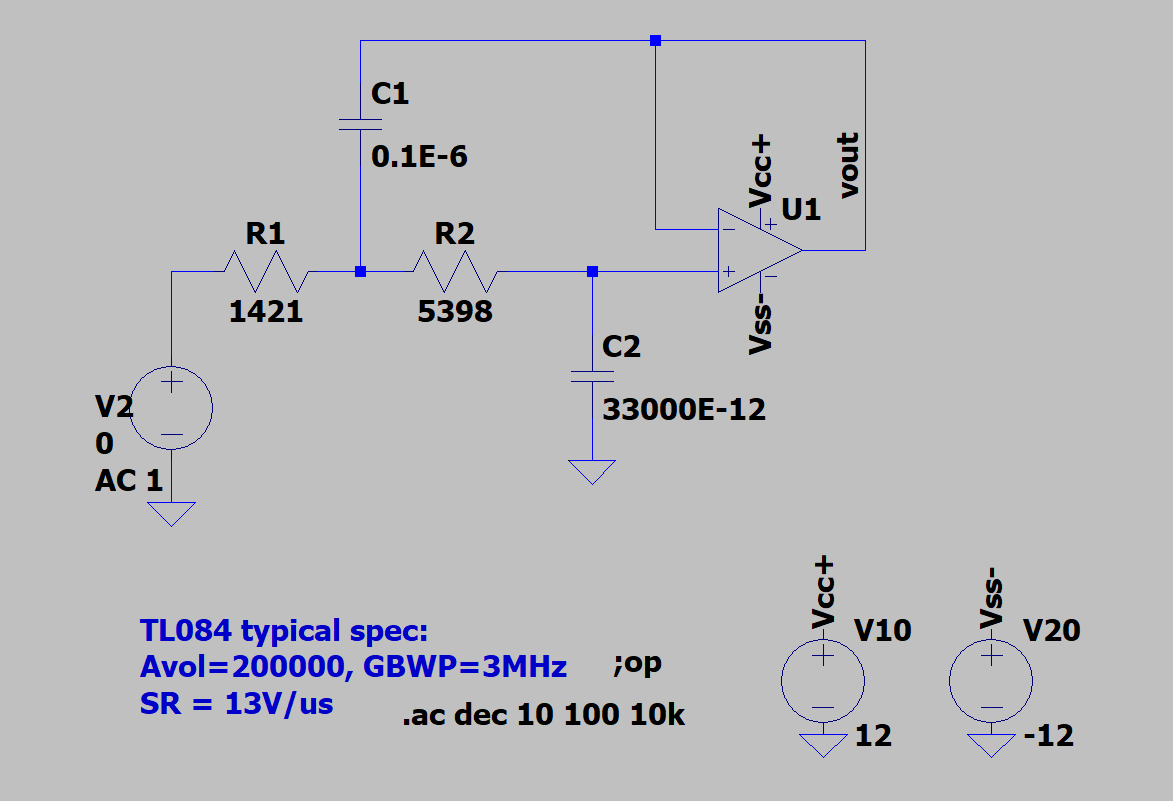

## LTSPICE Simulation Results

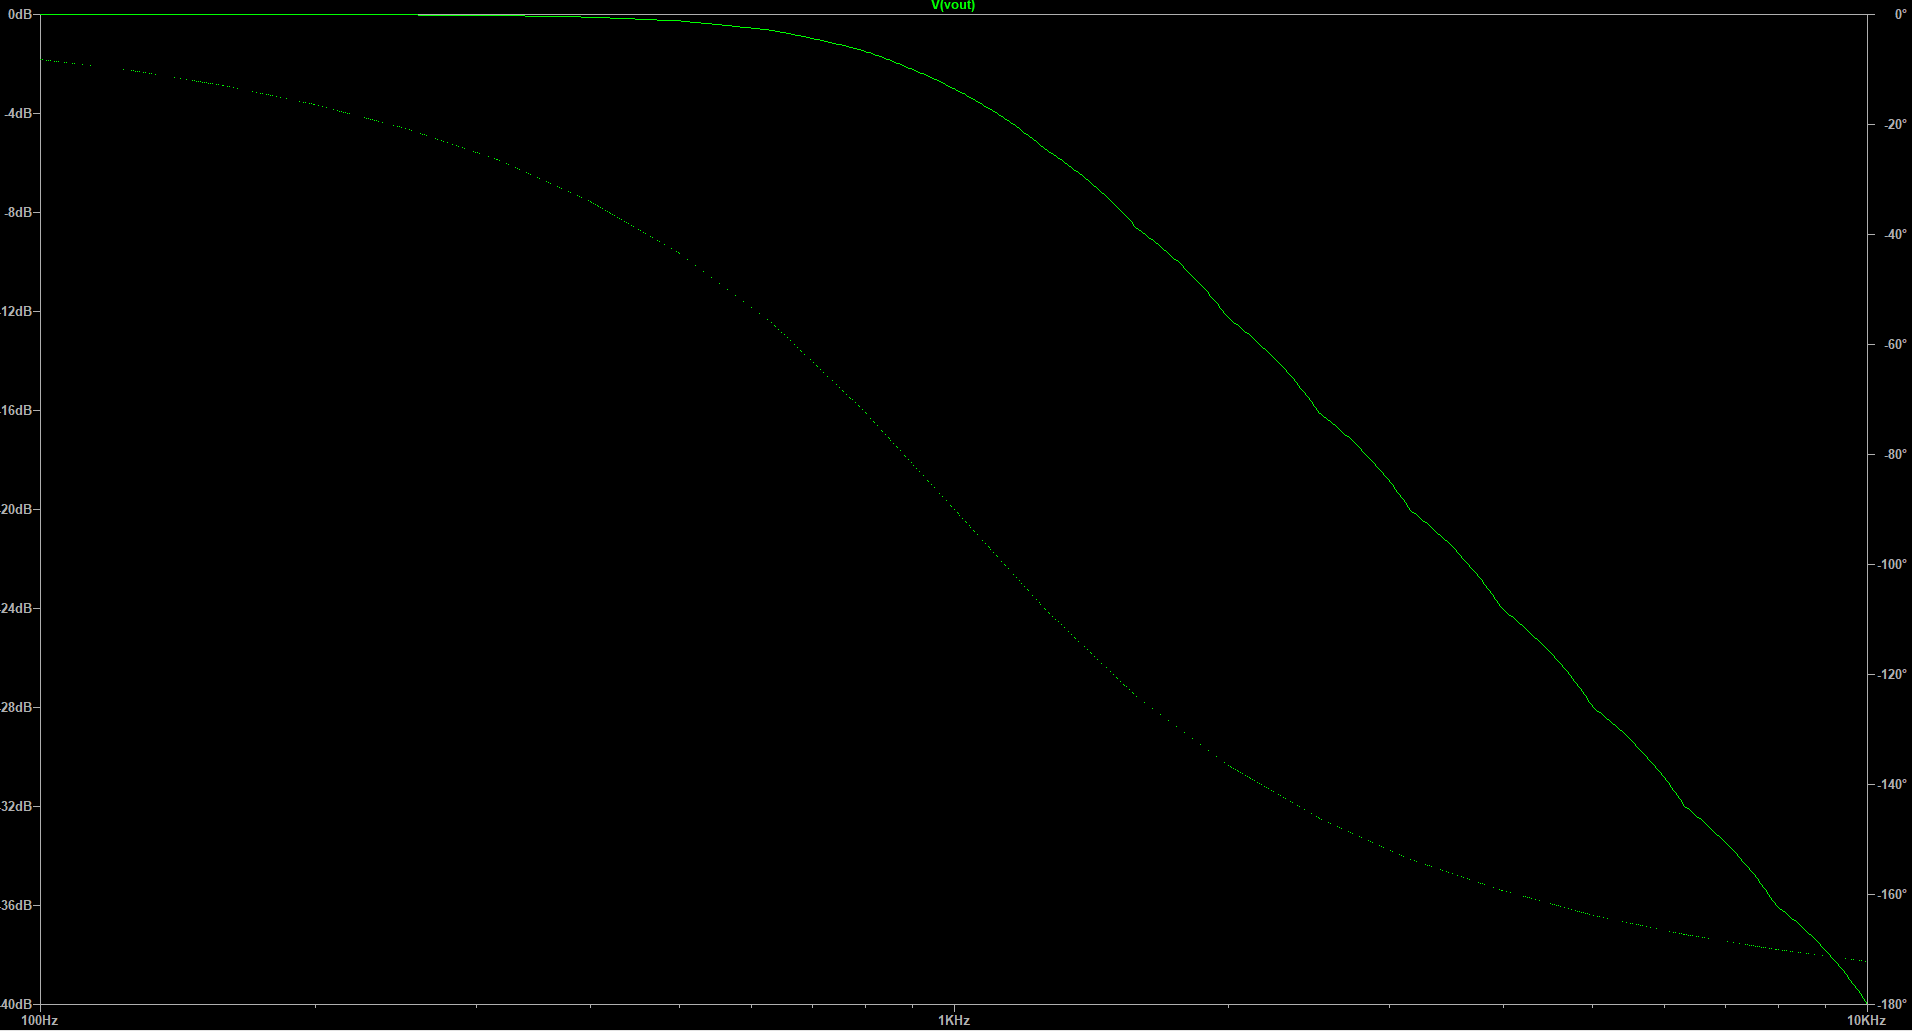

## Measurements

Record your measured data here and compare it against the theoretical results

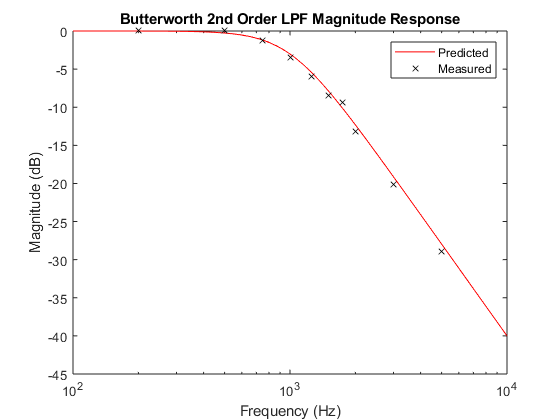

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [    [200, 8, 230e-6]
                [500, 8, 250e-6]
                [750, 6.88, 256e-6]
                [1000, 5.38, 270e-6]
                [1250, 4.02, 246e-6]
                [1500, 3, 230e-6]
                [1750, 2.70, 208e-6]
                [2000, 1.75, 188e-6]
                [3000, 0.792, 142e-6]
                [5000, 0.287, 90.4e-6]
                
                
           ];

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 8;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);
meas_delay = measured(:,3);
meas_phase = (-1)*360*meas_delay.*meas_freq;

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Butterworth 2nd Order LPF Magnitude Response')
legend('Predicted', 'Measured')

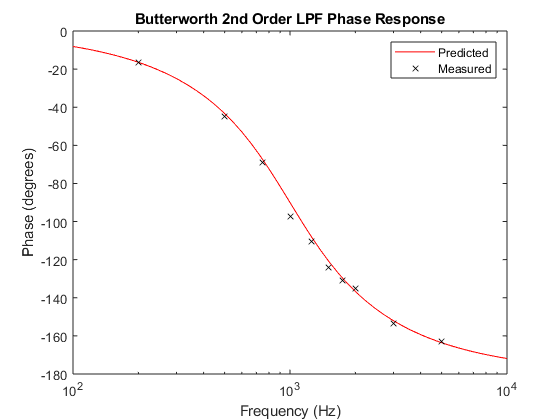


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Butterworth 2nd Order LPF Phase Response')
legend('Predicted', 'Measured')